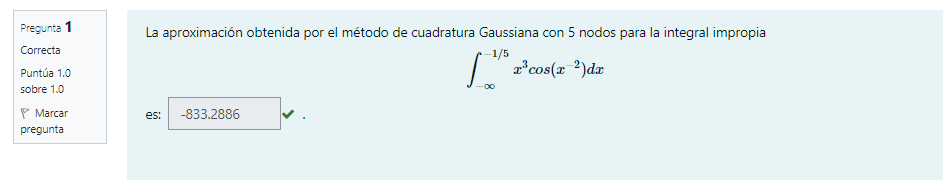

% INTEGRAL IMPROPIA
syms x
f = x^3*cos(x^(-2));
f = matlabFunction(f,"vars",{x});
a=-inf;
b=-1/5;
N = 5 % Cantidad de nodos;
[quad, raices, nodos, coefs] = impropias(f, a, b, N) %Esta funcion calcula integrales
%Impropias

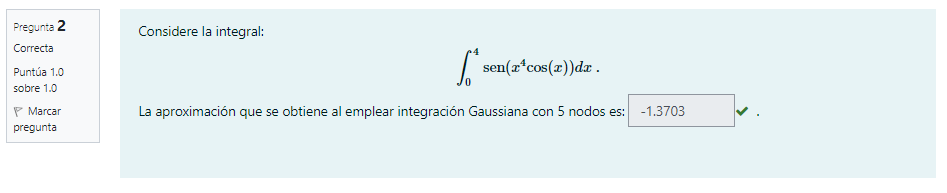

%INTEGRACION GAUSSIANA
syms x
f = sin(x^4*cos(x))
f = matlabFunction(f,"vars",{x});
a=0;
b=4;
N = 5 % numero de nodos
[quad, raices, nodos, coefs] = GaussLegendre( f, a, b, N)

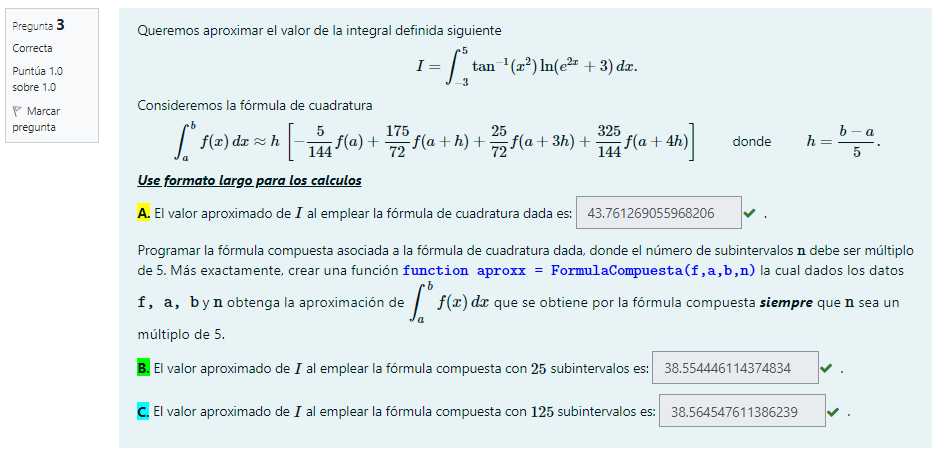

prueba:

a=0; b=15 ;M = 15; h = (b-a)/15;
x=a:h:b

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15



x(1)

ans = 0

x(15)

ans = 14

x(1:5:M)

ans =      0     5    10


x(2:5:M)

ans =      1     6    11


x(4:5:M)

ans =      3     8    13


x(5:5:M)

ans =      4     9    14


Con la prueba, se resuelve que:

syms x
f = atan(x^2)*log(exp(2*x)+3)

$$f = \log\left({\mathrm{e}}^{2\,x}+3\right)\,\mathrm{atan}\left(x^{2}\right)$$

f = matlabFunction(f);

% Se crea la rutina cuadratura_M5
format long
s_5 = Cuadratura_M5(f,-3,5,5) %Con M=5 sub invervalos

s =   43.761269055968199


s_5 =   43.761269055968199


s_25 = Cuadratura_M5(f,-3,5,25) %Con M=25 sub invervalos

s =   38.554446114374834


s_25 =   38.554446114374834


s_125 = Cuadratura_M5(f,-3,5,125) %Con M=125 sub invervalos

s =   38.564547611386239


s_125 =   38.564547611386239


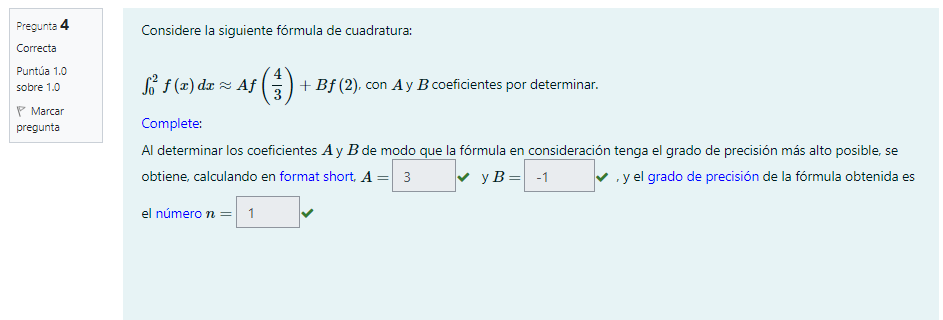

n=1000;
syms x
a=0;b=2;
for k=0:n
    g= x^k;
    if k==0
        f= @(x) 1;
    else
        f=matlabFunction(g);
    end
    aprox=(3*f(4/3)-f(2));
    int(g,a,b);
    if int(g,a,b)==aprox
        continue
    else
        break
    end
end
if k==0
    grado_de_precision=0
else
    grado_de_precision=k-1
end

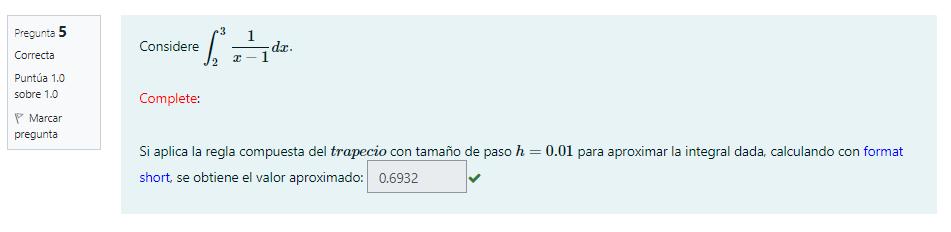

syms x
f = 1/(x-1)
f = matlabFunction(f,'Vars',{x});
a=2;b=3;
M=(b-a)/0.01;
approx = traprl(f,a,b,M)